Load files

% gps = csvread('gps.csv');
% imu = csvread('imu_donut.csv');
% imu_d = csvread('imu_drive.csv');

Read Data

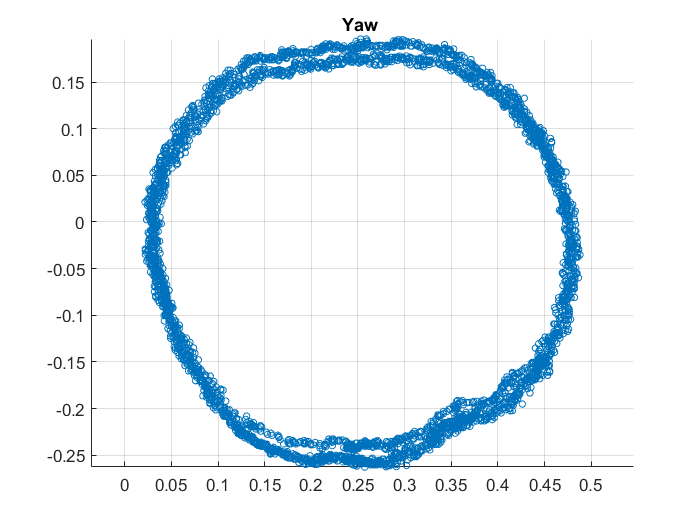

x_mag = imu.MagFieldmagnetic_fieldy;
y_mag = imu.MagFieldmagnetic_fieldx;
scatter(x_mag,y_mag,15)
title("Yaw ")
grid on
axis equal
hold off

Fitting to an ellipse to determine hard iron error offset

hold off

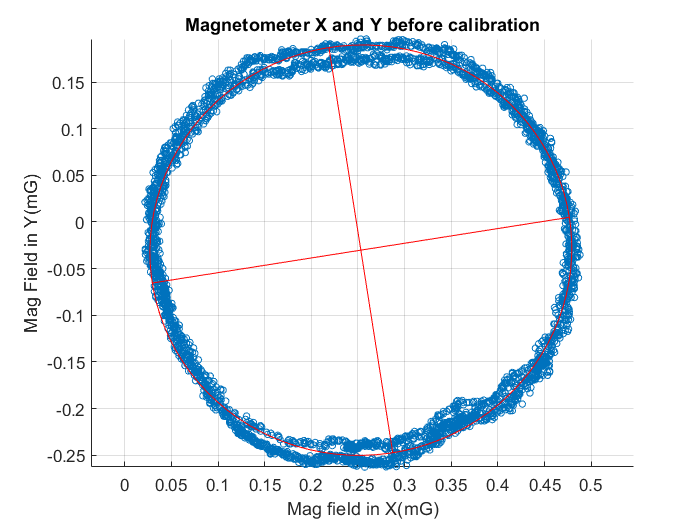

ellipse_t_ini = struct with fields:
             a: 0.2264
             b: 0.2199
           phi: -0.1563
            X0: 0.2453
            Y0: -0.0692
         X0_in: 0.2531
         Y0_in: -0.0302
     long_axis: 0.4527
    short_axis: 0.4398
        status: ''


scatter(x_mag, y_mag,15)
hold on
grid on
axis equal
title("Magnetometer X and Y before calibration")
xlabel("Mag field in X(mG)")
ylabel("Mag Field in Y(mG)")
ellipse_t_ini = fit_ellipse(x_mag,y_mag,1)

Hard Iron --Translating to origin 0,0

hold off

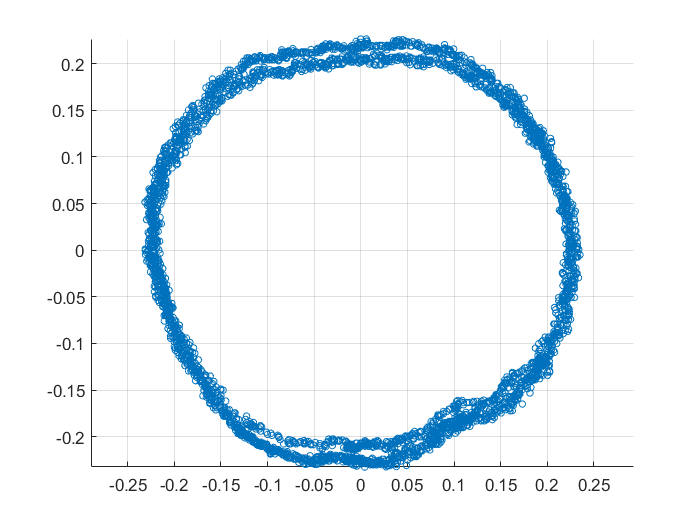

xcal = x_mag - ellipse_t_ini.X0_in;
ycal = y_mag - ellipse_t_ini.Y0_in;
m_trans = [xcal ycal];
scatter(xcal,ycal,15)
axis equal
grid on

Ellipse plot

hold off

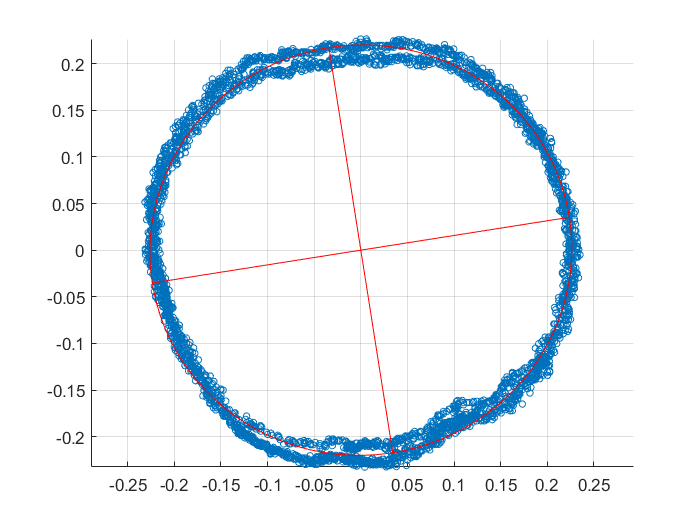

ellipse_t = struct with fields:
             a: 0.2264
             b: 0.2199
           phi: -0.1563
            X0: 3.6809e-17
            Y0: 1.5613e-17
         X0_in: 3.3929e-17
         Y0_in: 2.1152e-17
     long_axis: 0.4527
    short_axis: 0.4398
        status: ''


scatter(xcal,ycal,15)
hold on
grid on
axis equal
ellipse_t = fit_ellipse(xcal,ycal,1)

Soft iron -- Transformation  

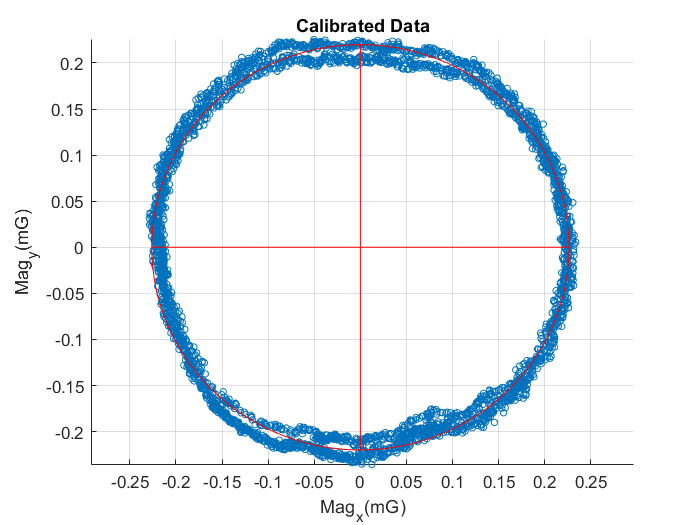

hold off

theta = ellipse_t.phi

theta = -0.1563

%theta = atan(0.03521416/0.223612)
t_mat = [cos(theta) -sin(theta); sin(theta) cos(theta)]

t_mat =     0.9878    0.1557
   -0.1557    0.9878


m_rot = t_mat * m_trans';
scatter(m_rot(1,:),m_rot ...
    (2,:),15)
hold on
grid on
fit_ellipse(m_rot(1,:),m_rot(2,:),1)

ans = struct with fields:
             a: 0.2264
             b: 0.2199
           phi: 0
            X0: 4.8410e-17
            Y0: -1.7347e-17
         X0_in: 4.8410e-17
         Y0_in: -1.7347e-17
     long_axis: 0.4527
    short_axis: 0.4398
        status: ''


title("Calibrated Data")
ylabel('Mag_y(mG)')
xlabel('Mag_x(mG)')
axis equal